# One versus one

This question uses a subset of the iris data - only the sepal widths and sepal lengths for all three classes:

clear all;
load('multiclass.mat', 'examples', 'labels');

This question is about training and visualising a set of Support Vector Machines (SVMs) in a one versus one (OVO) configuration in order to solve a multiclass problem. You should use the whole dataset (without splitting) for training. Note that the dataset has already been z-score standardised.

Marks are available for:

- An appropriate call to train a set of OVO SVMs on the whole dataset, with default parameters [3 marks]

- An appropriate call to train a *second* set of OVO SVMs on the whole dataset, using the kernel trick with an RBF kernel and a KernelScale of 0.4 [3 marks]

- Extending the `visualiseSVMs()` function, below, to give a helpful visualisation of any 2D model, `m`, trained by the `fitcecoc()` function (the visualisation should at least include the decision boundaries and the original training data) [8 marks]

- Using the `visualiseSVMs()` function you have developed to produce a visualisation of each of the two sets of SVMs you have trained [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:
%call to train a set of OVO SVMs on the whole dataset, with default parameters
m = fitcecoc(examples, labels, 'Coding', 'onevsone');

%crate SVM template with kernel trick with an RBF kernel and a KernelScale of 0.4
t = templateSVM('KernelFunction','rbf','KernelScale', 0.4)

t = Fit template for classification SVM.

                     Alpha: [0×1 double]
             BoxConstraint: []
                 CacheSize: []
             CachingMethod: ''
                ClipAlphas: []
    DeltaGradientTolerance: []
                   Epsilon: []
              GapTolerance: []
              KKTTolerance: []
            IterationLimit: []
            KernelFunction: 'gaussian'
               KernelScale: 0.4000
              KernelOffset: []
     KernelPolynomialOrder: []
                  NumPrint: []
                        Nu: []
           OutlierFraction: []
          RemoveDuplicates: []
           ShrinkagePeriod: []
                    Solver: ''
           StandardizeData: []
        SaveSupportVectors: []
            VerbosityLevel: []
                   Version: 2
                    Method: 'SVM'
                      Type: 'classification'


ans = 150×2 table
    sepal_width    sepal_length
    ___________    ____________

       1.0156        -0.89767  
     -0.13154         -1.1392  
      0.32732         -1.3807  
     0.097889         -1.5015  
        1.245         -1.0184  
       1.9333        -0.53538  
      0.78617         -1.5015  
      0.78617         -1.0184  
     -0.36097          -1.743  
     0.097889         -1.1392  
       1.4745        -0.53538  
      0.78617           -1.26  
     -0.13154           -1.26  
     -0.13154         -1.8638  
       2.1627       -0.052331  
       3.0805        -0.17309  


ans = 150×1 categorical array
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 


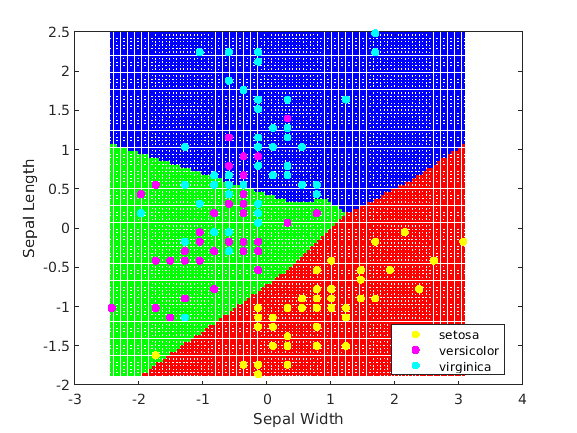


%call to train a second set of OVO SVMs on the whole dataset, using the
%kernel trick with an RBF kernel and a KernelScale of 0.4, parsing in
%previously made template using 'learners' name value pair
m2 = fitcecoc(examples,labels,'Coding','onevsone','Learners',t);

%produce a visualisation of each of the two SVMs that have been trained
figure(4)
visualiseSVM(m)

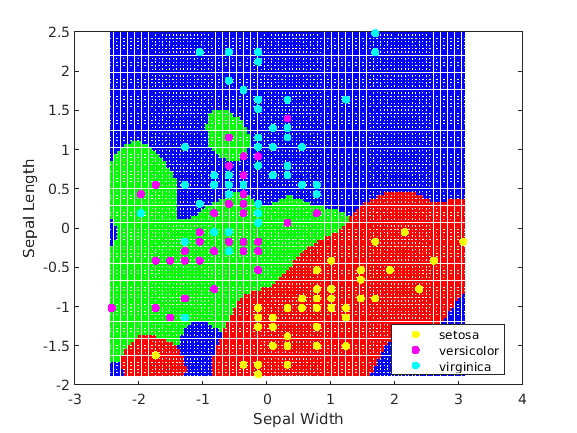

ans = 150×2 table
    sepal_width    sepal_length
    ___________    ____________

       1.0156        -0.89767  
     -0.13154         -1.1392  
      0.32732         -1.3807  
     0.097889         -1.5015  
        1.245         -1.0184  
       1.9333        -0.53538  
      0.78617         -1.5015  
      0.78617         -1.0184  
     -0.36097          -1.743  
     0.097889         -1.1392  
       1.4745        -0.53538  
      0.78617           -1.26  
     -0.13154           -1.26  
     -0.13154         -1.8638  
       2.1627       -0.052331  
       3.0805        -0.17309  


ans = 150×1 categorical array
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 


figure(5)
visualiseSVM(m2)

function visualiseSVM(m)

    % Hint: for any model, m, trained with fitcsvm(),
    % you can access the data used to train it with:
    m.X
    m.Y
    
    % Add as many lines of code as you need below:
    x_min = min(m.X{:,1});
    x_max = max(m.X{:,1});
    x_jump = (x_max - x_min) / 100; %find the max, min and jump values for X
    
    y_min = min(m.X{:,2});
    y_max = max(m.X{:,2});
    y_jump = (y_max - y_min) / 100; %find the max, min and jump values for Y
    
    xs = [];
    ys = [];

    for x = x_min:x_jump:x_max %loop for each possible x value
        for y = y_min:y_jump:y_max %loop for each possible x value
            %record the current coordinate
            xs(end+1,1) = x; 
            ys(end+1,1) = y;
        end
    end
    
    predictions = predict(m, [xs ys]); %generate a prediction using model parsed into this function, give all possible x and y values found as parameters

    gscatter(xs, ys, predictions) %plot prediction
    xlabel('Sepal Width')
    ylabel('Sepal Length')

    hold on
    gscatter(m.X{:,1}, m.X{:,2}, m.Y, 'ymc') %plot original example values

end